# PIV data visualization tool

## Load PIV data

snap.cs = {'18deg'}; snap.case_num = char(snap.cs);

%! store struct u & loc (contains flow field and mask) in workspace

FS = 'FontSize'; IN = 'Interpreter'; LT = 'Latex'; MS = 'MarkerSize'; 
LW = 'LineWidth'; FN = 'FontName'; TN = 'Times New Roman'; DN = 'DisplayName';

## scalar image

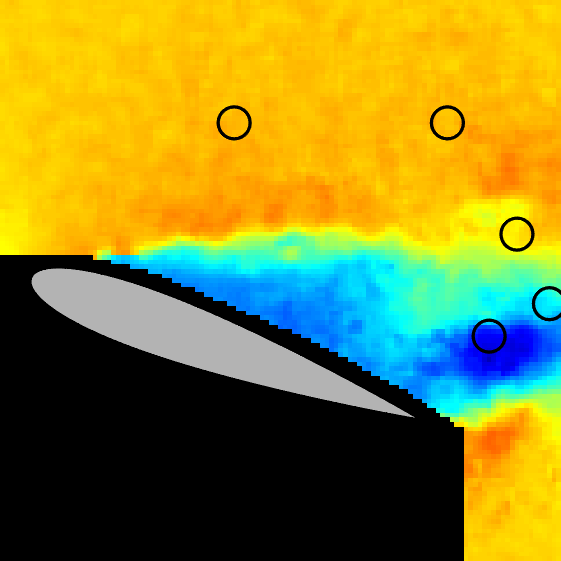

senstmp = randperm(size(u.Uorg,1),5)';
fig_u = F_fig_sensor(u.field(loc.normal),zeros(121,121),...
    -10,20,loc.normal,senstmp);
[wingx,wingy]=F_wingread('NACA0015.txt');
F_wingdraw(snap.case_num,wingx,wingy);


%     dirn = './figures/u/';
%     if ~isfolder(dirn)
%         mkdir(dirn)
%     end
% 
%     filen = [dirn,sprintf('%06i',ifig),'_u']
%     F_save_fig(filen)